**Calcium Analysis**

**Clear the workspace**

clear all
clc

**Import excel spreadsheet from ImageJ or NISEl **

Frame    Cell 1    Cell 2    Etc

1            Value    Value    Value

2            Value    Value    Value

File = uigetfile('*.xlsx');
[Pre_data, Pre_headers] = xlsread(File);
Pre_headers = Pre_headers(2,:);
Data = Pre_data(:,3:end-1);
Data_headers = Pre_headers(1, 3:end-1);
Frame_column = Pre_data(:,1);
Frame_header = 'Frame';
[NumberofRows, NumberofColumns] = size(Data);
Max_value = max(max(Data));
Time = linspace(0, 5, NumberofRows);
fps=7;

%fps = round(str2double(inputdlg('What is the fps rate?')));

**Plot Raw Data**

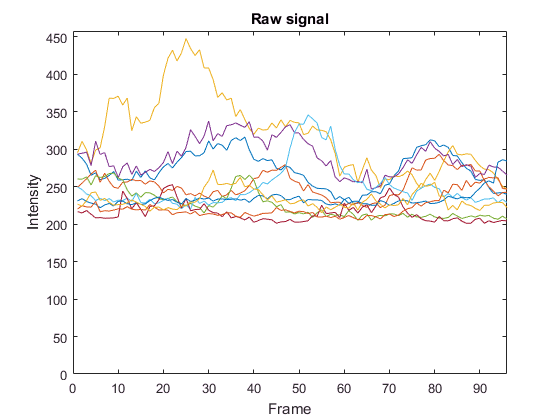

Figure1 = figure;
plot(Frame_column, Data)
axis([0 NumberofRows 0 Max_value+10])
title('Raw signal')
ylabel('Intensity')
xlabel('Frame')

**Calcium Analysis for Astrocytes 10-12-2018**

1st: Define the baseline (F0): F0 = mean of the lowest 1 seconds of each trace (first 1 seconds, = 15fps = 15 frames)

2nd: Calculate DF/F0

3rd: Use the function findpeaks to find the Calcium spikes, adding the condition that the peaks have to be bigger than the standard deviation of the DF/F0 trace

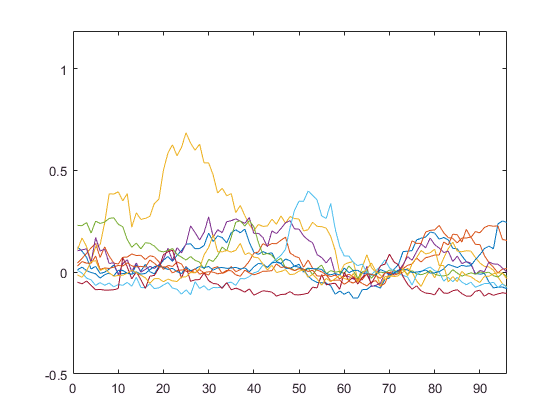

Mean = mean(Data(65:75, :));
DeltaFoverF = (Data-Mean)./Mean;
Max_value2=max(max(DeltaFoverF));
plot(DeltaFoverF)
axis([0 NumberofRows -0.5 Max_value2+0.5])

% vline([3658 7316 10974 14630 18286], {'r:', 'r:','r','r:', 'r:'})
%vline(3658)
    %vline(7316)
    %vline(10974)
    %vline(14630)
    %vline(18286)

**% Smooth data (temporal smoothing, window size = 1 second)**

 window = ones(fps,1)/fps;
 Smoothed = convn(DeltaFoverF, window, 'same');
 Figure = figure;
 plot(Smoothed)
 vline(1000)
 % If want to use Smoothed for posterior analysis, substitute DeltaFoverF for Smoothed below


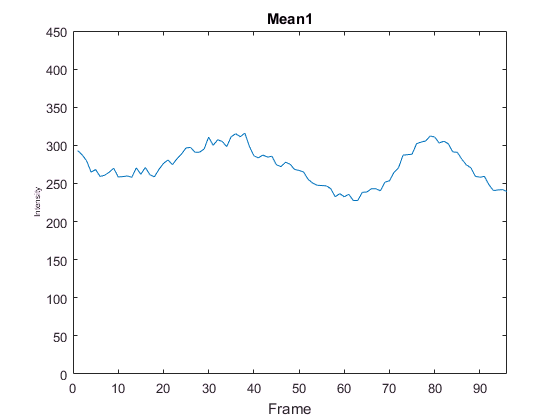

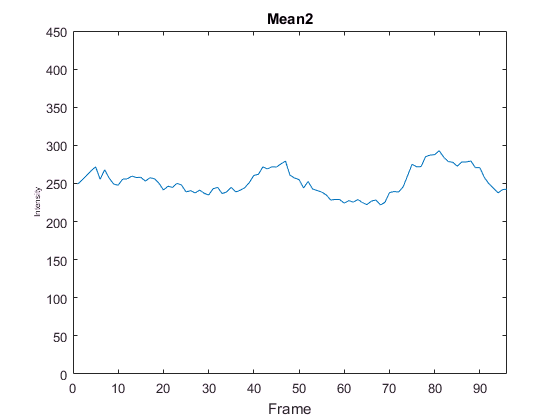

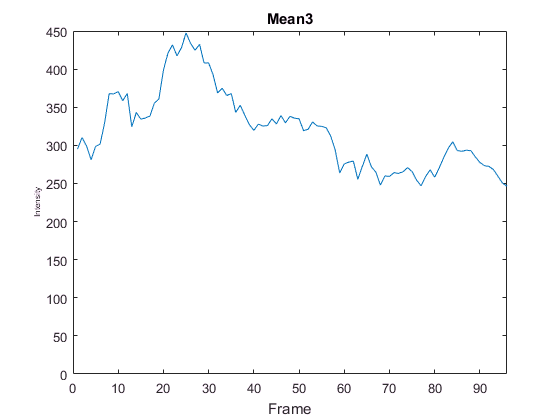

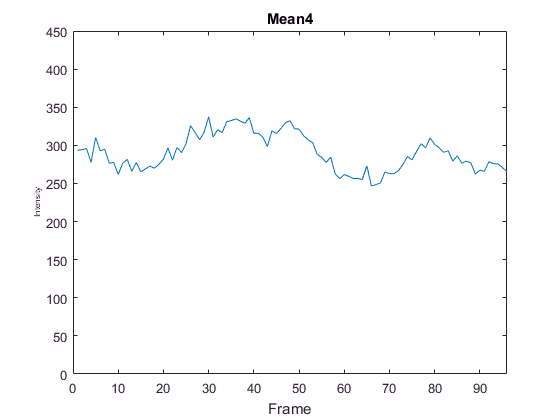

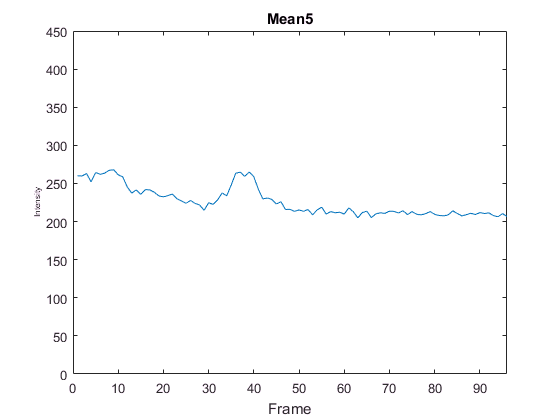

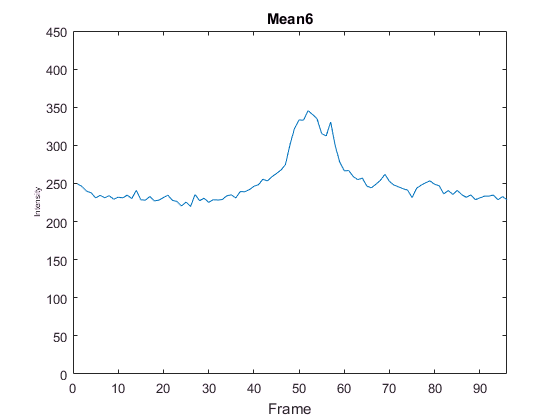

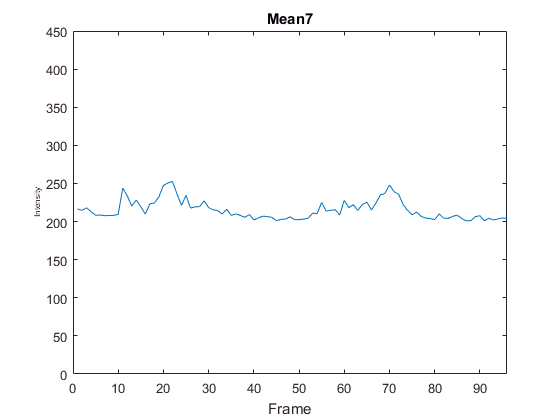

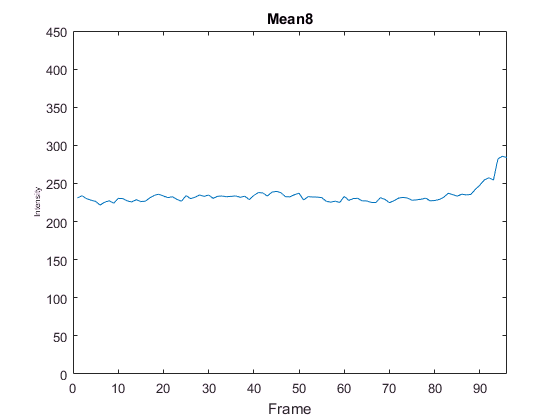

%PRint each graph of delta F over F separately and saves as pdfs on desktop
 for i = 1:NumberofColumns
    Result(i)=figure;
    plot(Data(:,i));
 

    %plot specifications
    axis([0 NumberofRows 0 450]);
    title(Data_headers(i));
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 6)
    %vline([3658 7316 10974 14630 18286], {'r:', 'r:','r','r:', 'r:'})
    %vline(917)
    %vline(1067)
    %vline(1223)
    %vline(1372)
    %vline(1524)
    saveas(Result(i), sprintf('result%d.pdf',i))
end

Save df/f0 as excel

baseline001=DeltaFoverF;
xlswrite('post-thc003DFoverF0.xlsx', baseline001);

Combine pdfs in one

append_pdfs('Gcamp6f astrocyte.pdf', 'result1.pdf', 'result2.pdf', 'result3.pdf', 'result4.pdf', 'result5.pdf', 'result6.pdf', 'result7.pdf', 'result8.pdf', 'result9.pdf', 'result10.pdf')

**Plot Delta F over F graphs**

%Plot first graph:
 findpeaks(Smoothed(:,1)), 'MinPeakProminence', std(DeltaFoverF(:,1))


%For some reason, it doesn't work for the first:
for i=1:NumberofColumns
    figure(i)
    [peak{i},locpeak{i}]=findpeaks(DeltaFoverF(:,i), 'MinPeakProminence', std(DeltaFoverF(:,i)));
    findpeaks(DeltaFoverF(:,i), 'MinPeakProminence', std(DeltaFoverF(:,i)));
end

%Works to create each graph separately

% a=ones(numel(locpeak{1,1}(:,1)));
% plot(locpeak{1,1}(:,1), a, '.k')
% axis([0 320, 0 2])

**Create plots with spikes in each cell**

%Plots only first one
a=ones(numel(locpeak{1,1}(:,1)));
plot(locpeak{1,1}(:,1), a, '.k')
axis([0 320, 0 2])

%for some reason, it does not plot the first one.
for i=1:NumberofColumns
    numela=ones([numel(locpeak{1,i}(:,1)) 1]);
    figure(i)
    plot(locpeak{1,i}(:,1), numela, '.k')
    axis([0 320, 0 2])
end